# Solution to *Wing Loading* exercise

The file `wingLoad.mat` contains the wing loading, `wload`, in lb/ft^2, and the maximum takeoff weight, `mtow`, in lb, for 68 aircraft.

## 1. Load data

load WingLoading

## 2. Create scatter plots

Using standard axes:

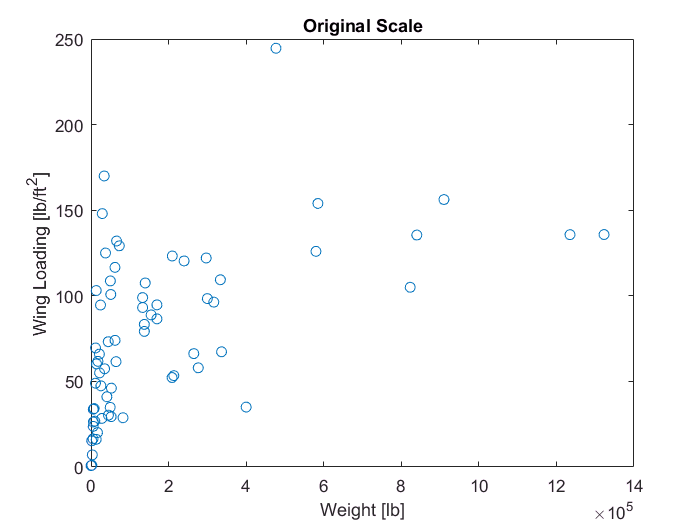

plot(mtow,wload,'o')
xlabel('Weight [lb]')
ylabel('Wing Loading [lb/ft^2]')
title('Original Scale')

Using logarithmic axes:

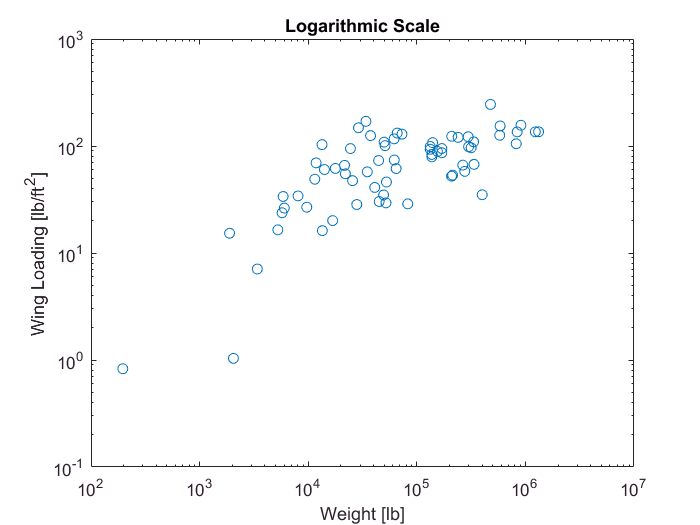

loglog(mtow,wload,'o')
xlabel('Weight [lb]')
ylabel('Wing Loading [lb/ft^2]')
title('Logarithmic Scale')

## 3. Basic fitting tool

Although the axes are logarithmic, the data is still in the original units. The Basic Fitting Tool is therefore trying to perform a linear fit, which appears nonlinear in the log-scale axes.

## 4. Create linear fit to log of data

wload_log = log10(wload);
mtow_log = log10(mtow);
c = polyfit(mtow_log,wload_log,1);

## 5. Calculate (logarithmic) wing loadings

x = linspace(2,6.5);
y = polyval(c,x);

## 6. Transform logarithmic values

wfit = 10.^x;
lfit = 10.^y;

## 7. Plot raw data on log-log axes

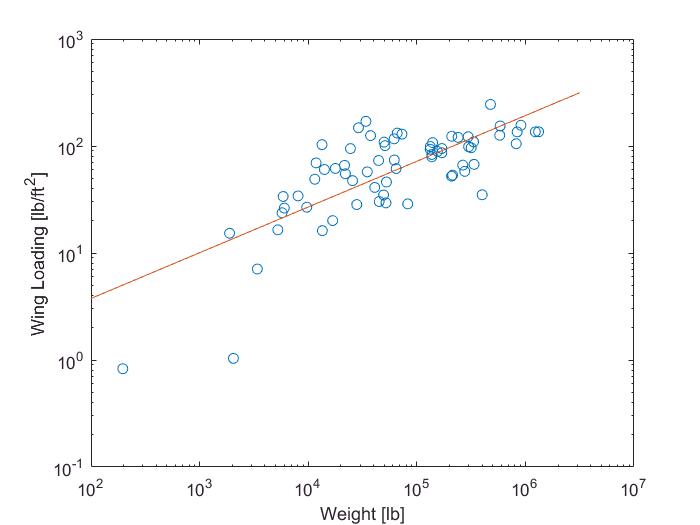

loglog(mtow,wload,'o')
hold on
loglog(wfit,lfit)
hold off
xlabel('Weight [lb]')
ylabel('Wing Loading [lb/ft^2]')